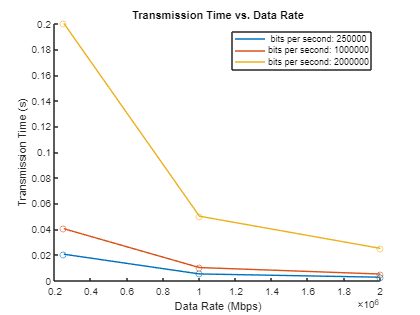

% Constants
distances = [1, 2, 10]; % Distances in meters
dataRates = [250e3, 1e6, 2e6]; % Data rates in bits per second
packetSize = 32; % Packet size in bytes
airDataRate = 2e6; % Air data rate in bits per second
transmissionEfficiency = 0.8; % Transmission efficiency as a decimal value

% Initialize figure
figure;
hold on;

% Loop over distances
for i = 1:length(distances)
    % Initialize arrays to store packet transmission times
    transmissionTimes = zeros(size(dataRates));
    
    % Loop over data rates
    for j = 1:length(dataRates)
        % Calculate the time required to transmit a single packet
        packetTime = (packetSize * 8) / airDataRate;
        
        % Calculate the total number of packets required to cover the distance
        totalPackets = ceil((distances(i) * 1000) / packetSize);
        
        % Calculate the transmission time for each packet
        transmissionTimes(j) = (totalPackets * packetTime) / (dataRates(j) * transmissionEfficiency);
    end
    
    % Plot transmission time vs. data rate for the current distance
    plot(dataRates, transmissionTimes /1e-6, 'o-');
end

hold off;
xlabel('Data Rate (Mbps)');
ylabel('Transmission Time (s)');
legend(cellstr(num2str(dataRates', 'bits per second: %d ')));
title('Transmission Time vs. Data Rate');